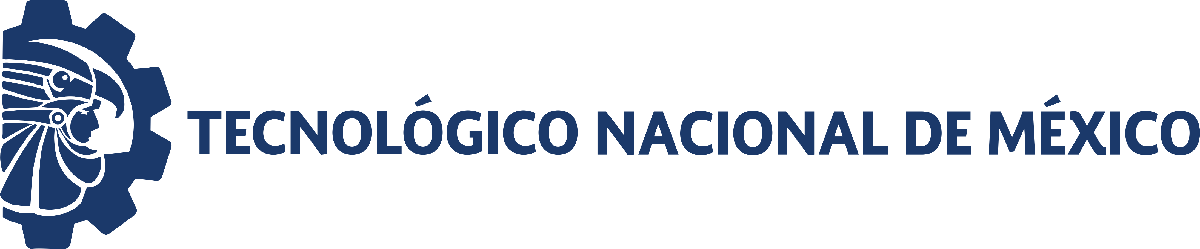                                 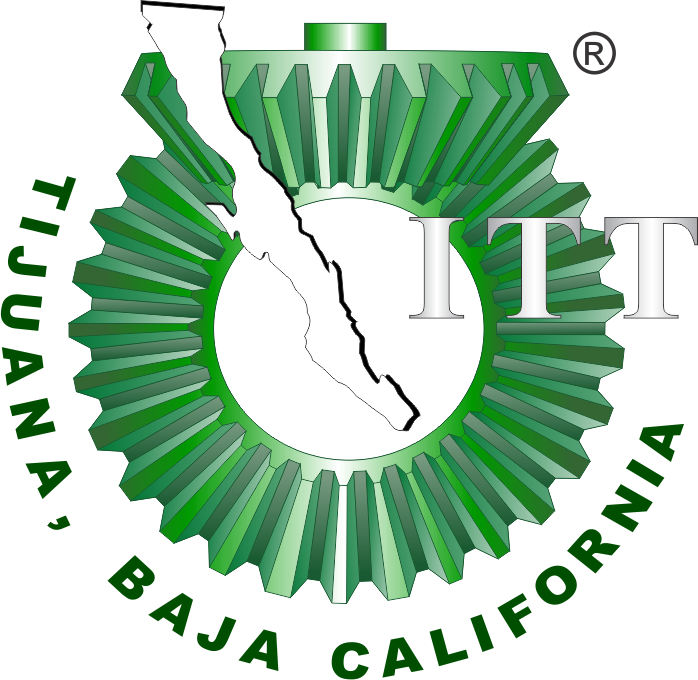

# Práctica tres: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

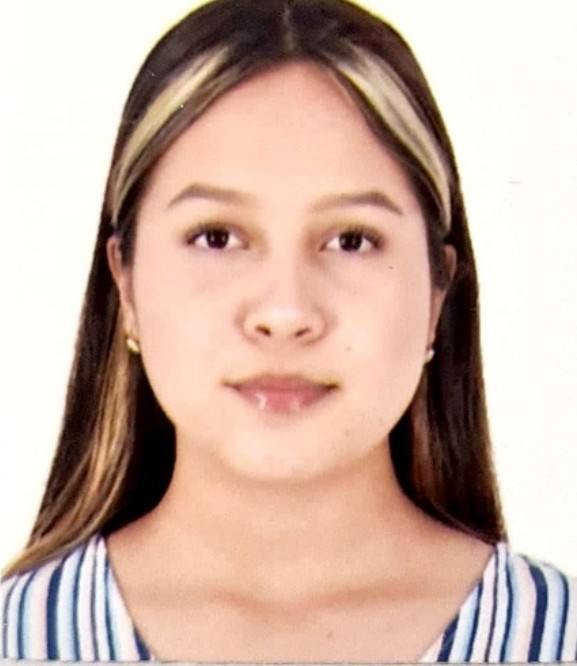

Nombre del alumno: **Sofia Cristina Duran Muñoz**

Número de control: **22211752**

Correo institucional: **l22211752@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Respuesta en lazo abierto

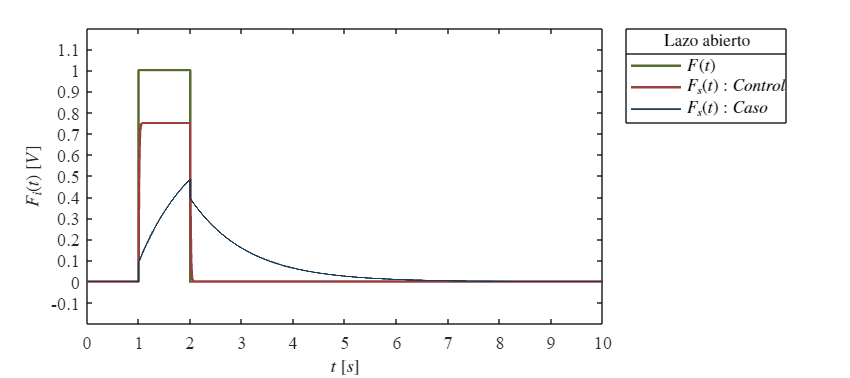

Signal = 'Lazo_abierto';
x1 = sim(file,parameters);
plotsignalsa(x1.t, x1.Fs, x1.Fs1, x1.Fs2, Signal)

## Respuesta en lazo cerrado

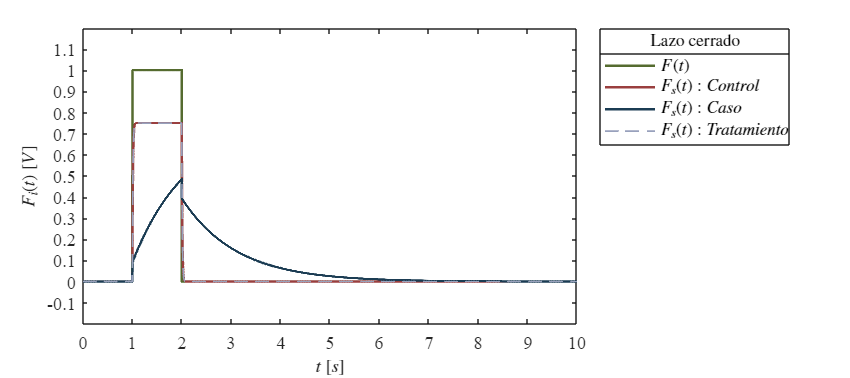

Signal = 'Lazo_cerrado';
x2 = sim(file,parameters);
plotsignals(x2.t, x2.Fs, x2.Fs1, x2.Fs2, x2.Fs3, Signal)

## Funcion: Respuesta a las señales

function plotsignals(t, Fs, Fs1, Fs2, Fs3, Signal)
    set(figure(),'Color', 'w')
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)
    hold on; grid off; box on;
    mycolors = [85,107,47;
                154,63,63;
                27,60,83;
                152,161,188;
                51,56,160;
                249,122,0]/255;
    colororder(mycolors)

    p = plot(t, Fs, '-', t, Fs1, '-', t, Fs2, '-', t, Fs3, '--', ...
        'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(4),'LineWidth', 1);
    
    L = legend('$F(t)$', '$F_{s}(t): Control$', '$F_{s}(t):Caso$', '$F_{s}(t):Tratamiento$');
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'on');
    title(L, ['Lazo cerrado'], 'FontSize', 10)

    xlabel('$t$ $[s]$', 'Interpreter', 'latex', 'FontSize', 11)
    ylabel('$F_i(t)$ $[V]$', 'Interpreter', 'latex', 'FontSize', 11)

    xlim([0,10]); xticks(0:1:10);
    ylim([-0.2,1.2]); yticks(-0.1:0.1:1.1);

    exportgraphics(gcf, [Signal,'.pdf'], 'ContentType', 'vector')
    exportgraphics(gcf,[Signal, '.png'], 'ContentType', 'vector')
end

function plotsignalsa(t, Fs, Fs1, Fs2, Signal)
    set(figure(),'Color', 'w')
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8])
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)
    hold on; grid off; box on;
    mycolors = [85,107,47;
                154,63,63;
                27,60,83;
                152,161,188;
                51,56,160;
                249,122,0]/255;
    colororder(mycolors)

    p = plot(t, Fs, '-', t, Fs1, '-', t, Fs2, '-', ...
        'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(3),'LineWidth', 1);
    
    L = legend('$F(t)$', '$F_{s}(t): Control$', '$F_{s}(t):Caso$');
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'on');
    title(L, ['Lazo abierto'], 'FontSize', 10)

    xlabel('$t$ $[s]$', 'Interpreter', 'latex', 'FontSize', 11)
    ylabel('$F_i(t)$ $[V]$', 'Interpreter', 'latex', 'FontSize', 11)

    xlim([0,10]); xticks(0:1:10);
    ylim([-0.2,1.2]); yticks(-0.1:0.1:1.1);

    exportgraphics(gcf, [Signal,'.pdf'], 'ContentType', 'vector')
    exportgraphics(gcf,[Signal, '.png'], 'ContentType', 'vector')
end
